# Improved Hough transform

Implementing the gradient-weighted Hough transform (GWHT), with potential improvements and refinements.

## Load image

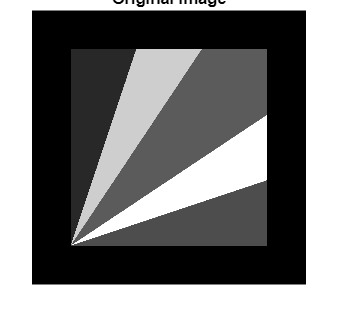

I = imread('testImage.png');
I = im2gray(I);
I = double(rescale(I));
figure()
imshow(I); title('Original image')

## Image preparation

### Maybe erode the lines a little

se = strel('disk', 0);
Ierode = imerode(I, se);

### Let's add a bit of blur and noise

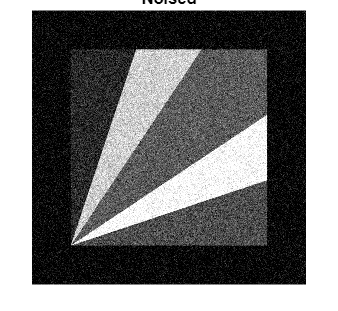

rng(123579);
Igauss = imgaussfilt(Ierode,sqrt(2), 'FilterSize',5);
Inoise = imnoise(Igauss);
imshow(Inoise); title('Noised')

### Calculating gradients

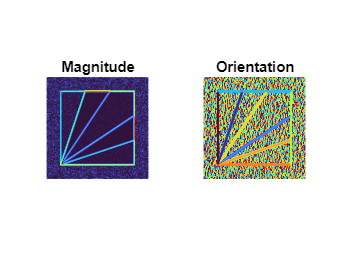

% Magnitude and direction
[Gxa, Gya] = gradientByRatio_v2(Inoise, 20);
IGMagnitude = hypot(Gxa,Gya);
IGOrientation = rad2deg(atan2(Gya,Gxa));

figure(); tiledlayout(1,2);
nexttile
imagesc(IGMagnitude); colormap turbo; axis image; axis off; title('Magnitude')
nexttile
imagesc(IGOrientation); colormap turbo; axis image; axis off; title('Orientation')

## Thresholding

% Thresholding
imScaledGradient = rescale(IGMagnitude);
% otsuLevel = graythresh(imScaledGradient);
otsuLevels = multithresh(imScaledGradient,2)

otsuLevels =     0.1176    0.3765


imOtsu = imbinarize(imScaledGradient,otsuLevels(1));

Compare otsu levels

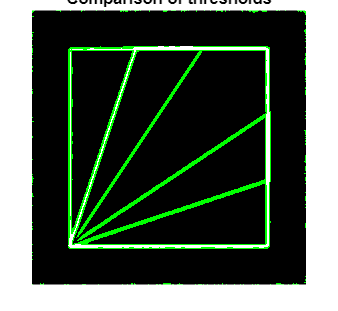

figure();imshowpair(imbinarize(imScaledGradient,otsuLevels(1)), ...
    imbinarize(imScaledGradient,otsuLevels(2))); title('Comparison of thresholds')

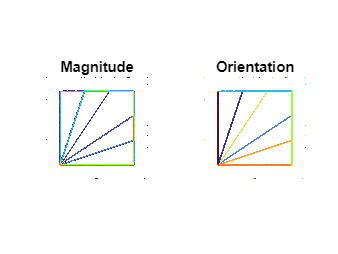

% threshVal = log(1.5276);
% imThreshold = IGMagnitude>otsuLevel;

% Region reduction
CC = bwconncomp(imOtsu);
regionSizes = cellfun(@length,CC.PixelIdxList);
largeEnoughIdx = find(regionSizes>100);
p = regionprops(CC,"Area");
[~,maxIdx] = maxk([p.Area],2);
BW2 = cc2bw(CC,"ObjectsToKeep",maxIdx);

% Masks
mask = imOtsu;
maskedOrientation   = immultiply(IGOrientation,mask); % Take only the data from the thresholded image
maskedMagnitude     = immultiply(IGMagnitude,mask);
maskedOrientation(maskedOrientation==0) =NaN;
maskedMagnitude(maskedMagnitude==0)     =NaN;

figure(); tiledlayout(1,2); title('Masked')
nexttile
h1 = imagesc(maskedMagnitude); colormap turbo; axis image; axis off; title('Magnitude')
set(h1, 'AlphaData', ~isnan(maskedMagnitude))
nexttile
h2 = imagesc(maskedOrientation); colormap turbo; axis image; axis off; title('Orientation')
set(h2, 'AlphaData', ~isnan(maskedOrientation))

## Hough transformation

sHough = GWHT(maskedOrientation,maskedMagnitude);

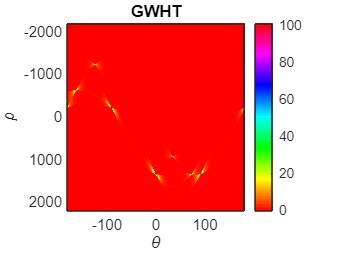

figure();
imagesc(sHough.hough, 'XData',sHough.theta, 'YData',sHough.rho);
colormap hsv; colorbar
xlabel('\theta'); ylabel('\rho'); 
title('GWHT')

## Extend Hough space

## Finding peaks

rhoSpace = sHough.rho;
numPeaks = 100;
integerHough = round(sHough.hough.*100); %Multiplication to improve accuracy of rounding
peaks = houghpeaks(integerHough, ...
    numPeaks, ...
    "Threshold", ceil(0.1*max(integerHough(:))),...
    "NHoodSize", [51,51]);

So a suppression neighbourhood isn't necessarily the best thing, since it means that "peaks" on the edges of the cut out zone will be considered (when they're not really peaks)

Instead, I should develop/implement some peak-climbing algorithm

## Peak optimisation

The goal here is to find initially many peaks, and then cut them down to the significant ones.

Find the magnitude of each peak

linearIdx = sub2ind(size(sHough.hough), peaks(:,1), peaks(:,2));
values = sHough.hough(linearIdx)

values =   101.5476
   89.6736
   85.1322
   62.0489
   57.8824
   57.6192
   57.5774
   54.3395
   52.2682
   49.9709


## Plotting peaks

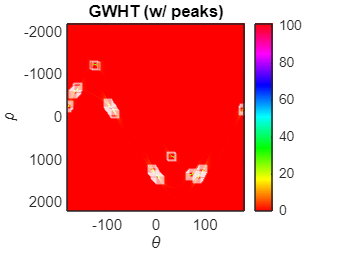

figure();
imagesc(sHough.hough, 'XData',sHough.theta, 'YData',sHough.rho);
colormap hsv; colorbar
xlabel('\theta'); ylabel('\rho'); 
title('GWHT (w/ peaks)')
x = sHough.theta(peaks(:,2)); y = sHough.rho(peaks(:,1));
hold on
plot(x,y,'s','color','white');
hold off

## Peak clustering

Using DBSCAN to associate detected peaks which belong to the same true peak together.

Consider a weighted averaging to find the "true" peak.

## Reconstruct lines

for j=1:length(peaks)
    pk = peaks(j,:);
    % Find a new mask for that peak. Within a range of the peak angle
    pkAngle = sHough.theta(pk(2));
    pkMask = zeros(size(mask));
    pkMask(maskedOrientation>(pkAngle-10) & maskedOrientation<(pkAngle+10)) = 1;
    pkLine = houghlines(pkMask, sHough.theta,rhoSpace,pk,...
        "FillGap",50, "MinLength", 100);

    if j==1 % For the first one, initialise the new big struct
        sLines = pkLine;
    else
        sLines = [sLines, pkLine];
    end
end

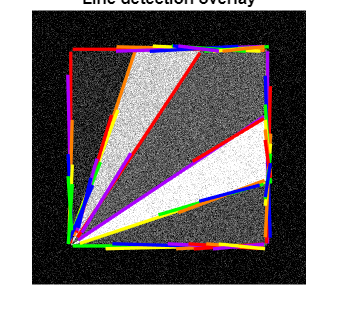

tLines = struct2table(sLines);
thetaRhoVals = [sLines.theta;sLines.rho]';
uniqueVals = unique(thetaRhoVals,"rows");
colours = prism(length(uniqueVals));

for i=1:length(uniqueVals) %for each unique value
    idx = and(any(thetaRhoVals == uniqueVals(i,1),2), ...
        any(thetaRhoVals == uniqueVals(i,2),2)); % Matching rows
    tLines.label(idx) = i;
end

figure, imshow(Inoise), hold on
for k = 1:height(tLines)
   xy = [tLines.point1(k,:); tLines.point2(k,:)];
   colour = colours(tLines.label(k),:);
   plot(xy(:,1),xy(:,2),'LineWidth',2,'Color',colour);
end
title('Line detection overlay');

hold off